# Sample 8-2

## 離散コサイン変換

可分離変換

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Discrete cosine transform

Separable transforms

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### 2変量の配列定義

(Definition of bivariate array)

X = [ 0 2 ; 4 6 ]

X =      0     2
     4     6


### 単変量変換行列の定義

(Definition of univariate transform)

- 回転行列(rotation matrix)

            
$$\mathbf{A}_{\theta} = \left(\begin{array}{cc} \cos\theta & -\sin\theta \\ \sin\theta & \cos\theta \end{array}\right)$$


- 行列 $\mathbf{A}_\theta$による変換

            
$$\mathbf{y} = \mathbf{A}_\theta\mathbf{x}$$


Atheta = @(theta) [cos(theta) -sin(theta) ; sin(theta) cos(theta)];
theta = -pi/4;
A = Atheta(theta)

A =     0.7071    0.7071
   -0.7071    0.7071


### 順変換の分離処理

(Separate process of the forward transform)

        
$$\mathbf{Y} = \mathbf{AXA}^T$$


fwdT = @(x) A*x*A.';
Y = fwdT(X)

Y =     6.0000    2.0000
    4.0000    0.0000


### 逆変換の分離処理

(Separate process of the inverse transform)

        
$$\mathbf{X} = \mathbf{A}^{-1}\mathbf{YA}^{-T}$$


invA = inv(A)

invA =     0.7071   -0.7071
    0.7071    0.7071


invT = @(y) invA*y*invA.'; 
R = invT(Y)

R =    -0.0000    2.0000
    4.0000    6.0000


### 基底展開

(Basis expansion)

B00 = invT([1 0; 0 0])

B00 =     0.5000    0.5000
    0.5000    0.5000


B01 = invT([0 1; 0 0])

B01 =    -0.5000    0.5000
   -0.5000    0.5000


B10 = invT([0 0; 1 0])

B10 =    -0.5000   -0.5000
    0.5000    0.5000


B11 = invT([0 0; 0 1])

B11 =     0.5000   -0.5000
   -0.5000    0.5000


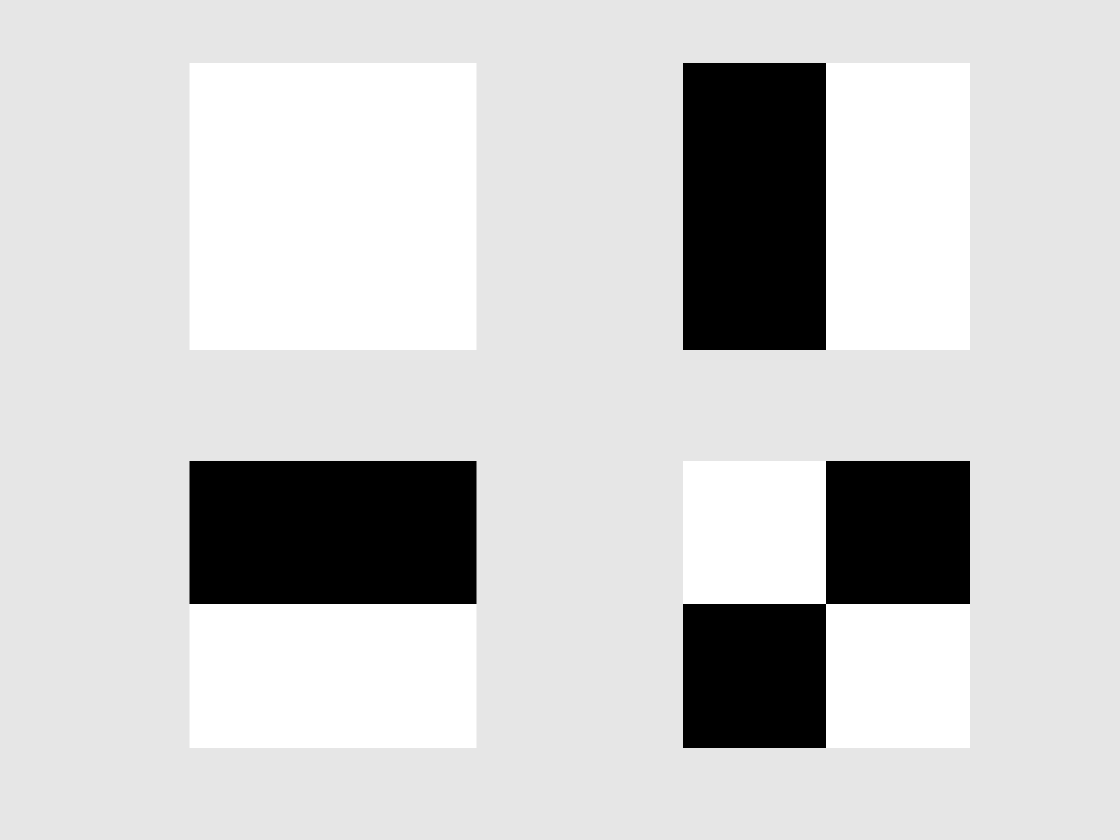

hfig1 = figure(1);
hfig1.Color = 0.9*[1 1 1];
subplot(2,2,1)
imshow(B00+.5)
subplot(2,2,2)
imshow(B01+.5)
subplot(2,2,3)
imshow(B10+.5)
subplot(2,2,4)
imshow(B11+.5)

Y(1,1)*B00 + Y(1,2)*B01 + Y(2,1)*B10 + Y(2,2)*B11

ans =    -0.0000    2.0000
    4.0000    6.0000


© Copyright, Shogo MURAMATSU, All rights reserved.